clear
syms x1(t) x2(t) x3(t) x4(t) gamma(t) f(t)
syms m g b1 b2
load("equations.mat")
f0_gamma0_equations

$$f0\_gamma0\_equations = \left(\begin{array}{c} \gamma \left(t\right)=g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)\\ f\left(t\right)=g\,m\,\sin\left(x_{1}\left(t\right)\right) \end{array}\right)$$

state_space_equations

$$state\_space\_equations(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=-\frac{b_{1}\,x_{2}\left(t\right)-\gamma \left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)+2\,m\,x_{2}\left(t\right)\,x_{3}\left(t\right)\,x_{4}\left(t\right)}{m\,{x_{3}\left(t\right)}^{2}}\\ \frac{\partial }{\partial t}x_{3}\left(t\right)=x_{4}\left(t\right)\\ \frac{\partial }{\partial t}x_{4}\left(t\right)=\frac{m\,x_{3}\left(t\right)\,{x_{2}\left(t\right)}^{2}+f\left(t\right)-b_{2}\,x_{4}\left(t\right)-g\,m\,\sin\left(x_{1}\left(t\right)\right)}{m} \end{array}\right)$$

x

$$x(t) = \left(\begin{array}{c} x_{1}\left(t\right)=\theta \left(t\right)\\ x_{2}\left(t\right)=\frac{\partial }{\partial t}\theta \left(t\right)\\ x_{3}\left(t\right)=r\left(t\right)\\ x_{4}\left(t\right)=\frac{\partial }{\partial t}r\left(t\right) \end{array}\right)$$

## The initial values for the model

% Physical values
g0 = 9.8036;
m0 = 1;
b10 = 0;
b20 = 0;

% Initial conditions
x10 = 1*pi/4;
x20 = 0;
x30 = 0.6;
x40 = 0;

% Boundaries
theta_min = 0;
theta_max = pi;
r_min = 0.1;
r_max = 1.1;

% Calculate the torques needed for object to be stationary at given point
f0_gamma0 = subs(f0_gamma0_equations, [m g x1(t) x3(t)], [m0 g0 x10 x30])

$$f0\_gamma0 = \left(\begin{array}{c} \gamma \left(t\right)=\frac{73527\,\sqrt{2}}{25000}\\ f\left(t\right)=\frac{24509\,\sqrt{2}}{5000} \end{array}\right)$$

% Obtain the calculated values
f0 = double(rhs(vpa([0 1]*f0_gamma0)))

f0 = 6.9322

gamma0 = double(rhs(vpa([1 0]*f0_gamma0)))

gamma0 = 4.1593

% f0 = 0;
% gamma0 = 0;

## Linearize a model

Jacobian_A = (jacobian(rhs(state_space_equations), [x1 x2 x3 x4]))

$$Jacobian\_A(t) = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ \frac{g\,\sin\left(x_{1}\left(t\right)\right)}{x_{3}\left(t\right)} & -\frac{b_{1}+2\,m\,x_{3}\left(t\right)\,x_{4}\left(t\right)}{\sigma_{1}} & \frac{2\,\left(b_{1}\,x_{2}\left(t\right)-\gamma \left(t\right)+g\,m\,\cos\left(x_{1}\left(t\right)\right)\,x_{3}\left(t\right)+2\,m\,x_{2}\left(t\right)\,x_{3}\left(t\right)\,x_{4}\left(t\right)\right)}{m\,{x_{3}\left(t\right)}^{3}}-\frac{g\,m\,\cos\left(x_{1}\left(t\right)\right)+2\,m\,x_{2}\left(t\right)\,x_{4}\left(t\right)}{\sigma_{1}} & -\frac{2\,x_{2}\left(t\right)}{x_{3}\left(t\right)}\\ 0 & 0 & 0 & 1\\ -g\,\cos\left(x_{1}\left(t\right)\right) & 2\,x_{2}\left(t\right)\,x_{3}\left(t\right) & {x_{2}\left(t\right)}^{2} & -\frac{b_{2}}{m} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m\,{x_{3}\left(t\right)}^{2} \end{array}$$

Linearized = subs(Jacobian_A, [m g b1 b2 x1(t) x2(t) x3(t) x4(t) gamma(t)], [m0 g0 b10 b20 x10 x20 x30 x40 gamma0])

$$Linearized(t) = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ \frac{24509\,\sqrt{2}}{3000} & 0 & \frac{24509\,\sqrt{2}}{1800}-\frac{585371577907253125}{15199648742375424} & 0\\ 0 & 0 & 0 & 1\\ -\frac{24509\,\sqrt{2}}{5000} & 0 & 0 & 0 \end{array}\right)$$

A = double(vpa(Linearized))

A =          0    1.0000         0         0
   11.5537         0  -19.2561         0
         0         0         0    1.0000
   -6.9322         0         0         0


eig(A)

ans =   -4.3237 + 0.0000i
   4.3237 + 0.0000i
  -0.0000 + 2.6722i
  -0.0000 - 2.6722i


Jacobian_B = (jacobian(rhs(state_space_equations), [f gamma]))

$$Jacobian\_B(t) = \left(\begin{array}{cc} 0 & 0\\ 0 & \frac{1}{m\,{x_{3}\left(t\right)}^{2}}\\ 0 & 0\\ \frac{1}{m} & 0 \end{array}\right)$$

Linearized = subs(Jacobian_B, [m x3(t)], [m0 x30])

$$Linearized(t) = \left(\begin{array}{cc} 0 & 0\\ 0 & \frac{25}{9}\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

B = double(vpa(Linearized))

B =          0         0
         0    2.7778
         0         0
    1.0000         0


## Now you can simulate the model by running draw.m script

## Linearizing in multiple operation points

n_thetas = 5;
bit_of_theta = (theta_max - theta_min) / n_thetas;
theta_op_ranges = [theta_min, theta_min + bit_of_theta];
for i = 1:n_thetas-1
    theta_op_ranges = [theta_op_ranges; theta_op_ranges(i,:)+bit_of_theta];
end
theta_op_ranges

theta_op_ranges =          0    0.6283
    0.6283    1.2566
    1.2566    1.8850
    1.8850    2.5133
    2.5133    3.1416


theta_op_points = (theta_op_ranges(:, 1) + theta_op_ranges(:, 2)) / 2

theta_op_points =     0.3142
    0.9425
    1.5708
    2.1991
    2.8274


n_rs = 2; 
bit_of_r = (r_max - r_min) / n_rs;
r_op_ranges = [r_min, r_min + bit_of_r];
for i = 1:n_rs-1
    r_op_ranges = [r_op_ranges; r_op_ranges(i,:)+bit_of_r];
end
r_op_ranges

r_op_ranges =     0.1000    0.6000
    0.6000    1.1000


r_op_points = (r_op_ranges(:, 1) + r_op_ranges(:, 2)) / 2

r_op_points =     0.3500
    0.8500


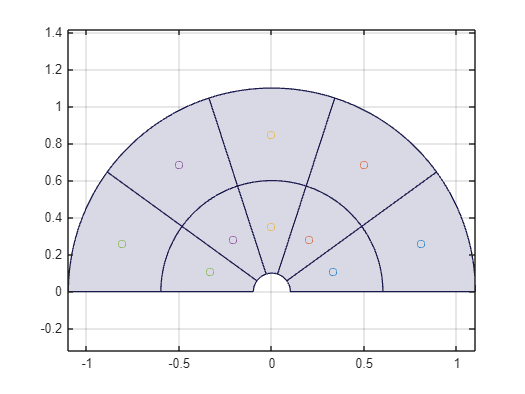

% Plot the operation points
plot_area(r_min, r_max, theta_min, theta_max); hold on;
plot_ranges(r_op_ranges, theta_op_ranges);
plot(r_op_points * cos(theta_op_points)', r_op_points * sin(theta_op_points)', 'o'); grid on; axis equal; hold off;

[THETA, R] = meshgrid(theta_op_points, r_op_points);
op_points = [THETA(:), R(:)]

op_points =     0.3142    0.3500
    0.3142    0.8500
    0.9425    0.3500
    0.9425    0.8500
    1.5708    0.3500
    1.5708    0.8500
    2.1991    0.3500
    2.1991    0.8500
    2.8274    0.3500
    2.8274    0.8500


clear R THETA
% Calculate the equilibrium forces and torques
op_points_f0_gamma0 = [];
for i=1:length(op_points)
    op_point_f0_gamma0 = subs(f0_gamma0_equations, [m g x1(t) x3(t)], [m0 g0 op_points(i,:)]);
    op_points_f0_gamma0 = [op_points_f0_gamma0; double(rhs(vpa([0 1]*op_point_f0_gamma0))), double(rhs(vpa([1 0]*op_point_f0_gamma0)))];
end
op_points_f0_gamma0

op_points_f0_gamma0 =     3.0295    3.2633
    3.0295    7.9252
    7.9313    2.0168
    7.9313    4.8980
    9.8036         0
    9.8036         0
    7.9313   -2.0168
    7.9313   -4.8980
    3.0295   -3.2633
    3.0295   -7.9252


% Calculate the matrices
op_A_matrices = zeros(4, 4, length(op_points));
op_B_matrices = zeros(4, 2, length(op_points));
for i=1:length(op_points)
    op_A = double(vpa(subs(Jacobian_A, [m g b1 b2 x1(t) x2(t) x3(t) x4(t) gamma(t)], [m0 g0 b10 b20 op_points(i,1) x20 op_points(i,2) x40 op_points_f0_gamma0(i,2)])));
    op_B = double(vpa(subs(Jacobian_B, [m x3(t)], [m0 op_points(i,2)])));

    op_A_matrices(:, :, i) = op_A;
    op_B_matrices(:, :, i) = op_B;
end

## Here are the results to be used in simulink

op_A_matrices

op_A_matrices = op_A_matrices(:,:,1) =

         0    1.0000         0         0
    8.6557         0  -76.1125         0
         0         0         0    1.0000
   -9.3238         0         0         0


op_A_matrices(:,:,2) =

         0    1.0000         0         0
    3.5641         0  -12.9049         0
         0         0         0    1.0000
   -9.3238         0         0         0


op_A_matrices(:,:,3) =

         0    1.0000         0         0
   22.6608         0  -47.0401         0
         0         0         0    1.0000
   -5.7624         0         0         0


op_A_matrices(:,:,4) =

         0    1.0000         0         0
    9.3309         0   -7.9757         0
         0         0         0    1.0000
   -5.7624         0         0         0


op_A_matrices(:,:,5) =

         0    1.0000         0         0
   28.0103         0         0         0
         0         0         0    1.0000
         0         0         0         0


op_A_matrices(:,:,6) =

         0

op_B_matrices

op_B_matrices = op_B_matrices(:,:,1) =

         0         0
         0    8.1633
         0         0
    1.0000         0


op_B_matrices(:,:,2) =

         0         0
         0    1.3841
         0         0
    1.0000         0


op_B_matrices(:,:,3) =

         0         0
         0    8.1633
         0         0
    1.0000         0


op_B_matrices(:,:,4) =

         0         0
         0    1.3841
         0         0
    1.0000         0


op_B_matrices(:,:,5) =

         0         0
         0    8.1633
         0         0
    1.0000         0


op_B_matrices(:,:,6) =

         0         0
         0    1.3841
         0         0
    1.0000         0


op_B_matrices(:,:,7) =

         0         0
         0    8.1633
         0         0
    1.0000         0


op_B_matrices(:,:,8) =

         0         0
         0    1.3841
         0         0
    1.0000         0


op_B_matrices(:,:,9) =

         0         0
         0    8.1633
         0         0
    1.0000       

theta_op_ranges

theta_op_ranges =          0    0.6283
    0.6283    1.2566
    1.2566    1.8850
    1.8850    2.5133
    2.5133    3.1416


r_op_ranges

r_op_ranges =     0.1000    0.6000
    0.6000    1.1000
